clear; clc; close all

tf = 10;
N = 40;

[nodes, ~] = clencurt(N);
tspan_ = ((flip(nodes)+1)/2).*tf;

## Manual PID Tuning

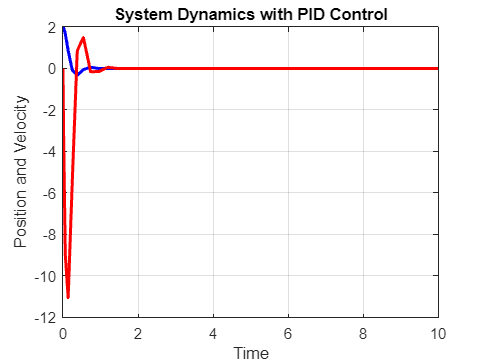

% Defining System Parameters
dynamics_params.mass = 1.0;                 % Mass of the object
dynamics_params.spring_constant = 5.0;      % Spring constant of the spring
dynamics_params.damping_coefficient = 0.1;  % Damping coefficient of the damper

% Initialize PID gains
gains = [-100, -0.0005, -10];

% Initial state [position; velocity; integral]
initial_state = [2; 0; 0];

% Desired state [desired_position; desired_velocity]
desired_state = [0; 0];

% Time span for simulation
% tspan = [0, 10];  % Start time and end time

% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains, dynamics_params, desired_state), tspan_, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control');
grid on;


cost_manual = cost(gains,desired_state,initial_state,dynamics_params,tspan_,ones(2))

cost_manual = 197.0303

## test consistency

D =  -533.5000  648.7890 -162.4476   72.3849  -40.8635   26.2741  -18.3497   13.5722  -10.4721    8.3475   -6.8284    5.7053   -4.8518    4.1885   -3.6629    3.2398   -2.8944    2.6091   -2.3709    2.1703   -2.0000    1.8545   -1.7295    1.6215   -1.5279    1.4465   -1.3755    1.3136   -1.2596    1.2125   -1.1716    1.1361   -1.1056    1.0795   -1.0576    1.0396   -1.0251    1.0140   -1.0062    1.0015   -0.5000
 -162.1973   80.9734  108.3542  -40.7375   21.8051  -13.6915    9.4419   -6.9311    5.3220   -4.2281    3.4505   -2.8780    2.4442   -2.1078    1.8419   -1.6280    1.4537   -1.3098    1.1898   -1.0888    1.0031   -0.9299    0.8670   -0.8128    0.7657   -0.7248    0.6892   -0.6581    0.6310   -0.6074    0.5868   -0.5690    0.5537   -0.5407    0.5297   -0.5206    0.5134   -0.5078    0.5039   -0.5015    0.2504
   40.6119 -108.3542   20.1802   65.2809  -27.2987   15.6718  -10.3432    7.4048   -5.5969    4.3998   -3.5640    2.9565   -2.5006    2.1497   -1.8737    1.6529   -1.4735    

integral =          0    0.0307    0.1162    0.2147    0.2519    0.2154    0.1833    0.1887    0.1941    0.1923    0.1923    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924    0.1924


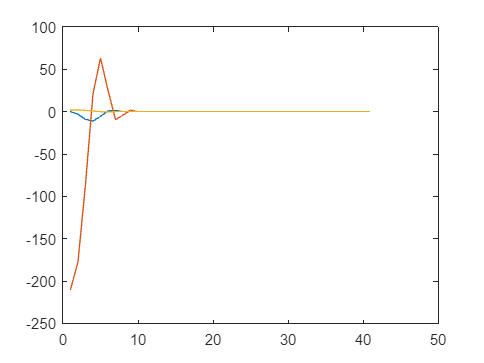

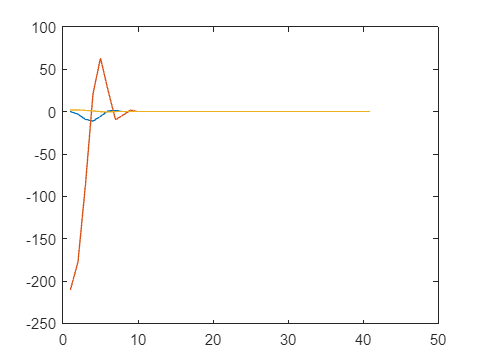

Z_test = zeros(6,length(y));

Z_test(1,:) = y(:,1).';
Z_test(2,:) = y(:,2).';
Z_test(3,:) = y(:,3).';
Z_test(4,1) = gains(1);
Z_test(5,1) = gains(2);
Z_test(6,1) = gains(3);


[~, res] = NonLinCon_PseudoSpectral(Z_test,initial_state,desired_state,dynamics_params,N,tf);


sum(res)

ans = 0.0110

res

res =          0
         0
         0
   -0.0000
   -0.0000
   -0.0015
    0.0002
    0.0001
    0.0005
    0.0020


## PID Gain Optimisation - ODE45

% interior point
options = optimoptions("fmincon","Display","iter",...
    "Algorithm","interior-point",...
    "EnableFeasibilityMode",true,...
    "SubproblemAlgorithm","cg");
gains_interiorP = fmincon(@(gains)cost(gains,desired_state,initial_state,dynamics_params,tspan,ones(2)),[-100;-0.01;-10],[],[],[],[],[],[],@(gains)DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan),options)

% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains_interiorP, dynamics_params, desired_state), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Interior Point Tuning');
grid on;

cost_interiorP = cost(gains_interiorP,desired_state,initial_state,dynamics_params,tspan,ones(2))

## PID Gain Optimisation - Genetic Algorithm

% Define the GA options
ga_options = optimoptions('ga', 'Display', 'iter', 'PopulationSize', 20, 'MaxGenerations', 25);

% Set the lower and upper bounds for the PID gains
ub = [-10, -0.0005, -1]; % Lower bounds for Kp, Ki, and Kd
lb = [-200, -0.06, -20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ga = ga(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, [], [], [], [], [], [], @(gains) DynamicConstODE(gains, desired_state, initial_state, dynamics_params, tspan), ga_options)


% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains_ga, dynamics_params, desired_state), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Genetic Algorithm Tuning');
grid on;

cost_ga = cost(gains_ga,desired_state,initial_state,dynamics_params,tspan,ones(2))

## PID Gain Optimisation - Particle Swarm

% Define the GA options
ps_options = optimoptions('particleswarm', 'Display', 'iter', 'SwarmSize', 100);

% Set the lower and upper bounds for the PID gains
ub = [-10, -0.0005, -1]; % Lower bounds for Kp, Ki, and Kd
lb = [-200, -0.06, -20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ps = particleswarm(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, [], [], ps_options)

% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, gains_ps, dynamics_params, desired_state), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Particle Swarm Tuning');
grid on;

cost_ps = cost(gains_ps,desired_state,initial_state,dynamics_params,tspan,ones(2))


## PID Gain Optimisation - with Pseudospectral Formulation

N = 21;

init = zeros(5, N+1);
% init(3,1) = -gains_ps(1);
% init(4,1) = -gains_ps(2);
% init(5,1) = -gains_ps(3);

options = optimoptions('fmincon','Display','iter','MaxFunctionEvaluations',1e5,'Algorithm','sqp',"EnableFeasibilityMode",true,'MaxIterations',5e3);

tf = 20; 
desired_state = [1; 0];
initial_state = [0; 0];
Q = ones(2);

[Z,~,flg] = fmincon(@(Z)cost_pseudospectral(Z,desired_state,Q,N,tf),init,[],[],[],[],[],[],@(Z)NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf),options);
gains_psuedospectral = Z(3:5,1).'

[nodes,~] = clencurt(N);
tspan_ = ((flip(nodes)+1)/2).*tf;

% Extract position and velocity for plotting
position = Z(1, :);
velocity = Z(2, :);

% Plot the results
figure;
plot(tspan_, position, 'b', 'LineWidth', 2);
hold on;
plot(tspan_, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('Optimizer Output - Psuedospectral Tuning');
grid on;



% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, -gains_psuedospectral, dynamics_params, desired_state), 1:0.1:tf, [0; 0; 0]);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Psuedospectral Tuning');
grid on;

cost_pseudospec = cost(-gains_psuedospectral,desired_state,[0; 0; 0],dynamics_params,tspan,ones(2))

## Non-Linear Constraint for Pseudospectral Optimisation

function [c,ceq] = NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf)
    
    state = Z(1:3,:);
    gains = Z(4:6,1);

    dummy = Z(4:6, 2:end);

    Kp = gains(1);
    Ki = gains(2);
    Kd = gains(3);

    c =[];
    % c(1) = Kp - 200;
    % c(2) = Ki - 0.06;
    % c(3) = Kd - 20;
    % c(4) = 10 - Kp;
    % c(5) = 0.0005 - Ki;
    % c(6) = 1 - Kd;

    % Use Guass-Quadrature integration to simulate system dynamics with PID
    error = state(1,:) - desired_state(1,:);
    % integral = zeros(size(error));
    % integral(:,1) = error(:,1);

    velocity_error = state(2,:) - desired_state(2,:);

    [~,wk] = clencurt(N);
    % wk = zeros(N+1);
    % wk(1) = 0;
    % 
    % [nodes,~] = clencurt(N);
    % tspan_ = ((flip(nodes)+1)/2).*tf;
    % for i = 1:N
    %     [~,weights] = clencurt(i);
    %     wk(i+1,1:i+1) = weights';
    %     wk(i+1,:) = wk(i+1,:)*tspan_(end-i+1)/2;
    % end

    % for i = 2:size(state,2)
    %     integral(:,i) = integral(:,i-1) + wk(i)*error(:,i);
    % end

    % for i = 1:1 % Detemines which variables error
    %     for j = 2:size(state,2) % Determines which node it is being calculated at
    %         integral(i,j) = sum(wk(j,:)*error(:,j));
    %     end
    % end

    D = -DCPeyret(N+1)

    % Unpack state variables
    position = state(1,:);
    velocity = state(2,:);
    integral = state(3,:) - desired_state(1)*wk.'


    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    input = Kp*error + Ki*integral + Kd*velocity_error;

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    figure()
    plot((2/tf)*D*state.')

    figure()
    plot([velocity; acceleration; position].')
    
    c_dynamics = ((2/tf)*D*state.').' - ([velocity; acceleration; position]);
    reshape(c_dynamics, [], 1);

    ceq_init = state(:,1) - initial_state;
    ceq_des = state(1:2,end) - desired_state;
    ceq_dummy = dummy;

    ceq = vertcat(reshape(ceq_init, [], 1),reshape(ceq_des, [], 1),reshape(c_dynamics, [], 1), reshape(ceq_dummy, [], 1));
end


### Cost Pseudospectral Optimisation

function J = cost_pseudospectral(Z,desired_state,Q,N,tf)

    [~,wk] = clencurt(N);
    
    state = Z(1:2,:);
    J = 0;
    for i = 1:N
        J = J + wk(i)*((state(:,i)-desired_state).'*Q*(state(:,i)-desired_state));
    end
    J = J*(tf/2);
end 

## System Dynamics Constraint Function - ODE

function [c,ceq] = DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan)
    c = [];

    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, gains, dynamics_params, desired_state), tspan, initial_state);
   
    ceq_init = y(1,:) - initial_state.';
    ceq_des = y(end,1:2) - desired_state.';

    ceq = vertcat(reshape(ceq_init,[],1),reshape(ceq_des,[],1));
end 

## Cost Function

function J = cost(gains,desired_state,initial_state,dynamics_params,tspan,R)
    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, gains, dynamics_params,desired_state), tspan, initial_state);
    
    J = 0;
    for timestep = 1:size(y,1)
        state = y(timestep,1:2);
        J = J + (state - desired_state.')*R*(state - desired_state.').';
    end 
end 

## Spring Mass Damper System Dynamics

function dydt = dynamics(t, state, gains, dynamics_params, state_f)
    % t: Time (not used in this function, but required for numerical integration)
    % state: State vector [position; velocity; integral]
    % gains: PID gains [Kp; Ki; Kd]
    % dynamics_params: struct containing system dynamic parameters (mass,
    % spring_constant, damping_coefficient)

    % Unpack state variables
    position = state(1);
    velocity = state(2);
    integral = state(3);

    % Unpack PID gains
    Kp = gains(1);
    Ki = gains(2);
    Kd = gains(3);

    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    % Compute input
    input = Kp*(position - state_f(1)) + Kd*(velocity - state_f(2)) + Ki*(integral - state_f(1)*t);

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    % Return the derivative of the state variables
    dydt = [velocity; acceleration; position];
end



## Chebyshev Pseudospectral Method

function [x,w] = clencurt(N)
    % File to compute CGL Nodes x and
    % Clenshaw-Curtis Quadrature Weights w

    theta = -pi*(0:N)'/N;
    x = cos(theta);

    w = zeros(N+1,1);
    i = 2:N;
    v = ones(N-1,1);

    if mod(N,2) == 0
        w(1) = 1/(N^2 -1);
        w(N+1) = w(1);

        for j = 1:0.5*N-1
           v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
        v = v - cos(N*theta(i))/(N^2 - 1);
    else
        % CHECK ODD CASE
        w(1) = 1/N^2;
        w(N+1) = w(1);

        for j = 1:0.5*(N-1)
            v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
    end
    w(i) = 2*v/N;
end

function D = DCPeyret(N)
    % Peyret's D matrix
    D = zeros(N);
    D(1,1) = (2*(N-1)^2 + 1)/6;
    D(N,N) = -(2*(N-1)^2 + 1)/6;
    m = 0:N-1;
    ndsP = cos(m*pi/(N-1));
    cbar = ones(N,1);
    cbar(1) = 2;
    cbar(N) = 2;
    
    for i = 1:N
        if i ~= 1 && i ~= N
            D(i,i) = -0.5*ndsP(i)/(1- ndsP(i)^2);
        end
        
        for j = setdiff(1:N,i)
            D(i,j) = cbar(i) * (-1)^(i + j) / (cbar(j) * (ndsP(i) - ndsP(j)));
        end
    end
end 
